# Example: Nonlinear System

The code below gives a reachability analysis example for nonlinear systems in CORA.

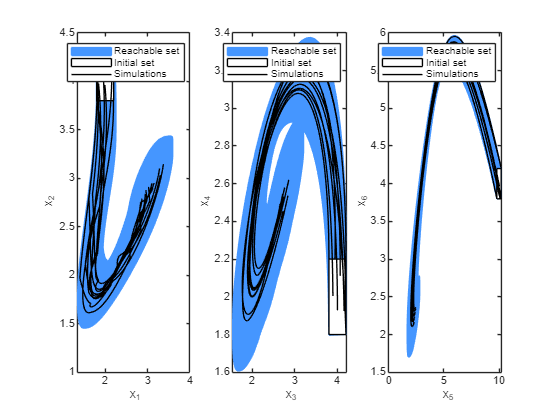

% System Dynamics ---------------------------------------------------------

% parameter
k = 0.015;
k2 = 0.01;
g = 9.81; 

% differential equations
f = @(x,u) [...
    u(1)+0.1+k2*(4-x(6))-k*sqrt(2*g)*sqrt(x(1));  % tank 1
    k*sqrt(2*g)*(sqrt(x(1))-sqrt(x(2)));          % tank 2
    k*sqrt(2*g)*(sqrt(x(2))-sqrt(x(3)));          % tank 3
    k*sqrt(2*g)*(sqrt(x(3))-sqrt(x(4)));          % tank 4
    k*sqrt(2*g)*(sqrt(x(4))-sqrt(x(5)));          % tank 5
    k*sqrt(2*g)*(sqrt(x(5))-sqrt(x(6)));          % tank 6
];

tank = nonlinearSys('tank',f);

% Parameters --------------------------------------------------------------

params.tFinal = 400;
params.R0 = zonotope([[2; 4; 4; 2; 10; 4],0.2*eye(6)]);
params.U = zonotope([0,0.005]);

% Reachability Settings ---------------------------------------------------

options.timeStep = 1;
options.taylorTerms = 4;
options.zonotopeOrder = 50;
options.alg = 'lin';
options.tensorOrder = 2;

options.lagrangeRem.simplify = 'simplify';

% Reachability Analysis ---------------------------------------------------

R = reach(tank, params, options);

% Simulation --------------------------------------------------------------

simOpt.points = 10;
simRes = simulateRandom(tank, params, simOpt);

% Visualization -----------------------------------------------------------

dims = {[1 2],[3 4],[5 6]};
figure;

for k = 1:length(dims)
    
    subplot(1,3,k); hold on; box on;
    projDim = dims{k};
    
    % plot reachable sets
    useCORAcolors("CORA:contDynamics")
    plot(R,projDim,'DisplayName','Reachable set');
    
    % plot initial set
    plot(R(1).R0,projDim, 'DisplayName','Initial set');
    
    % plot simulation results      
    plot(simRes,projDim,'DisplayName','Simulations');

    % label plot
    xlabel(['x_{',num2str(projDim(1)),'}']);
    ylabel(['x_{',num2str(projDim(2)),'}']);
    legend()
end